tsunamis = readtable("tsunamis.xlsx");

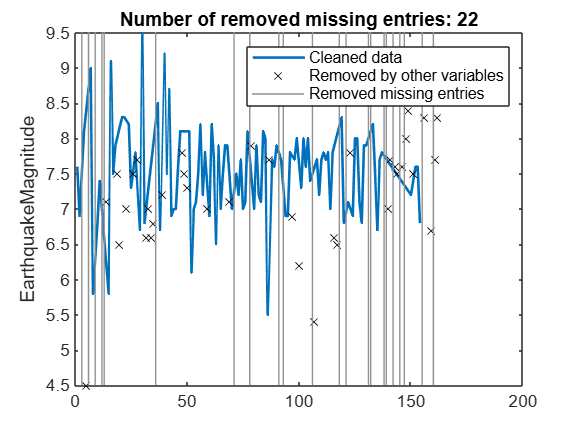

% Remove missing data
[tsunamisClean,missingIndices] = rmmissing(tsunamis, ...
    "DataVariables",["EarthquakeMagnitude","IidaMagnitude"]);

% Display results
figure
% Get locations of missing data
indicesForPlot = ismissing(tsunamis.EarthquakeMagnitude);
mask = missingIndices & ~indicesForPlot;

% Plot cleaned data
plot(find(~missingIndices),tsunamisClean.EarthquakeMagnitude,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot data in rows where other variables contain missing entries
plot(find(mask),tsunamis.EarthquakeMagnitude(mask),"x","SeriesIndex","none", ...
    "DisplayName","Removed by other variables")

% Plot removed missing entries
x = repelem(find(indicesForPlot),3);
y = repmat([ylim(gca) missing]',nnz(indicesForPlot),1);
plot(x,y,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(indicesForPlot))

hold off
legend
ylabel("EarthquakeMagnitude")

clear indicesForPlot mask x y

% Compute group summary
countryMeans = groupsummary(tsunamisClean,"Country","mean","IidaMagnitude")

countryMeans = 20x3 table
          Country           GroupCount    mean_IidaMagnitude
    ____________________    __________    __________________

    {'ALGERIA'         }         1                   1      
    {'CHILE'           }         4               2.025      
    {'COLOMBIA'        }         1                 2.3      
    {'COSTA RICA'      }         1                   1      
    {'FIJI'            }         1                   1      
    {'GREECE'          }         3              1.6333      
    {'INDIA'           }         1                -1.3      
    {'INDONESIA'       }        16              2.2263      
    {'JAPAN'           }        13                 1.6      
    {'JAPAN SEA'       }         1                   5      
    {'MEXICO'          }         7             0.41429      
    {'NICARAGUA'       }         1                 3.3      
    {'PAPUA NEW G

countryMeans = countryMeans(countryMeans.GroupCount > 1, :);
[~, idx] = max(countryMeans.mean_IidaMagnitude);
mostExtremeCountry = countryMeans(idx, :)

mostExtremeCountry = 1x3 table
    Country    GroupCount    mean_IidaMagnitude
    _______    __________    __________________

    {'USA'}        8               2.925       


% Extract the relevant columns
EQ = tsunamis.EarthquakeMagnitude;
Iida = tsunamis.IidaMagnitude;

% Remove rows where either is NaN
validIdx = ~isnan(EQ) & ~isnan(Iida);

EQ = EQ(validIdx);
Iida = Iida(validIdx);

coeffs = polyfit(EQ, Iida, 1);  % y = coeffs(1)*x + coeffs(2)
% IidaMagnitude ≈ coeffs(1) * EarthquakeMagnitude + coeffs(2)

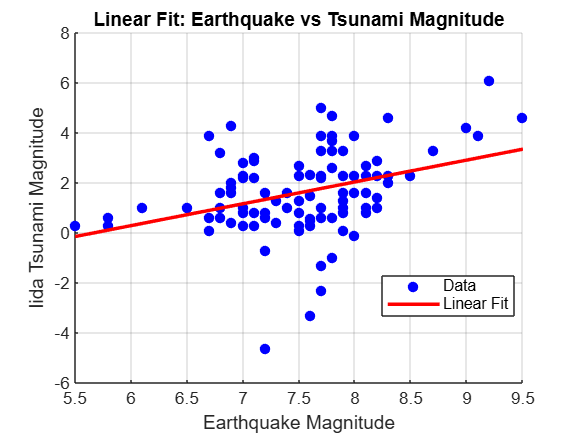

IidaFit = polyval(coeffs, EQ);

figure
scatter(EQ, Iida, 'b', 'filled')
hold on
plot(EQ, IidaFit, 'r-', 'LineWidth', 2)
xlabel('Earthquake Magnitude')
ylabel('Iida Tsunami Magnitude')
title('Linear Fit: Earthquake vs Tsunami Magnitude')
legend('Data', 'Linear Fit', 'Location', 'best')
grid on


r = corr(EQ, Iida);
fprintf('Correlation coefficient: %.3f\n', r);

Correlation coefficient: 0.359


predictedIida = polyval(coeffs, 4.0);
roundedIida = round(predictedIida, 2);
fprintf('Predicted tsunami magnitude at EQ = 4.0: %.2f\n', roundedIida);

Predicted tsunami magnitude at EQ = 4.0: -1.46
